## **Plotting Absolute Values and Fold Change of Enzyme Concentrations in Log-Scale**

#### This script loops semilogy plots for average non-optimized and optimized enzyme concentrations in a loop, creating panels for individual enzymes.

Import all required data in a separate script:

import_optimization_results; %import averages of ten replicates
%import_optimization_reps; % import ten replicates

Assign x and y for semilogy graphs - i.e x = Ci, y = protein concentration in mg m^-2.

Assign output variables to non-optimized and optimized protein data in linear and log scale :

y = cell(1, numel(sheet_names));
y_log = cell(1, numel(sheet_names));
y_fold = cell(1, numel(sheet_names));
%y_log_fold = cell(1, numel(sheet_names)); redundant

Run the loop to collect data:

for i = 1:numel(sheet_names)
    % Combine full data for non-optimized and optimized at each Ci
    y{1,i} = horzcat(results_data{1,1},results_data{2,i}(:,1));
    % Convert data to log scale
    y_log{1,i} = horzcat(log10(y{1,i}(:,1)),log10(y{1,i}(:,2))); % log x
    % Calculate y fold changes
    y_fold{1,i} = y{1,i}(:,2:end)./y{1,i}(:,1);
    % Calculate y_log fold changes - essentially the same as y fold since
    % the ratios of non-opt to opt are equal
    %y_log_fold{1,i} = y_log{1,i}(:,2:end)./y_log{1,i}(:,1);
end

Convert sheet_names into x values: 

Ci = str2double(sheet_names);
enzymes=string(cats);

Create output variables for all enzymes

enzyme_nopt_concs = zeros(size(cats,1),size(y,2)); 
all_opt_concs = zeros(size(cats,1),size(y,2)); 
all_opt_FC = zeros(size(cats,1),size(y,2)); 
all_opt_log_FC = zeros(size(cats,1),size(y,2)); 

CBB_indices = 1:8;
PR_indices = 10:16;
SS_indices = [9,17:23];

% Replace PR_constraints reaction IDs with enzyme names 

PR_constraints_protein(:,1) = cellstr(enzymes(PR_indices));

% Horizontally stack PR_limits values for each Ci by repeating col 2 of PR_constraints

PR_limits = cell2mat(repmat(PR_constraints_protein(:,2),1,15));

% Loop through all sheets and extract the values for specific enzymes

for j = 1:length(y{1,i}(:,2)) % For all enzymes
    for i = 1:numel(Ci)
    enzyme_nopt_concs(j,i) = y{1,i}(j,1); % take the non-optimized data from col 1
    all_opt_concs(j,i) = y{1,i}(j,2); % take the optimized data from col 2
    all_opt_FC(j,i) = y_fold{1,i}(j,1); 
    %all_opt_log_FC(j,i) = y_log_fold{1,i}(j,1); 
    end
end

Use a switch statement to choose whether to plot non-optimized and optimized absolute concentrations or fold changes for each enzyme panel:

plottype = input('Enter type of plot (opt/FC): ', 's');

Create CBB panel:

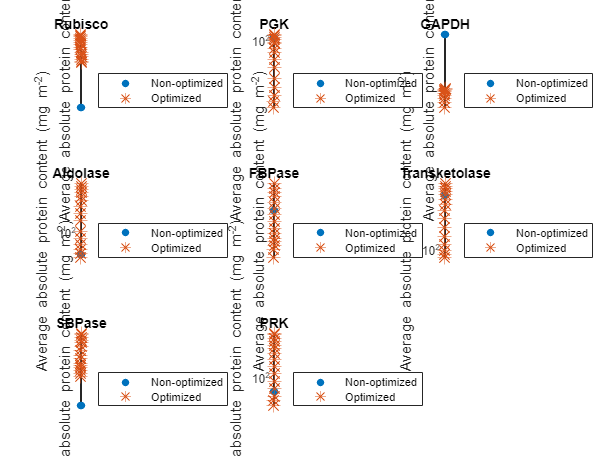

    figure;
    % Plot semilogy graphs of Ci (x) against absolute protein concentrations of individual enzymes 
    for j = 1:length(CBB_indices) % For each enzyme j 
        CBB_index = CBB_indices(j);
        nexttile
        switch (plottype)
        case 'opt'
        semilogy(Ci, enzyme_nopt_concs(CBB_index,:), '.', 'MarkerSize', 15);
        hold on
        semilogy(Ci, all_opt_concs(CBB_index,:), '*', 'MarkerSize', 10);
        hold on
        xlim([min(Ci), max(Ci)]); % Ci x axis limits
        ylim([0,inf]) % Protein y axis limits 
        xticks(Ci)
        xticklabels(Ci)
        yticks([0 10^1 10^2 10^3 10^4])
        yticklabels({'0','10^1','10^2','10^3','10^4'})
        xlabel('C_i (ppm)','FontSize', 10);
        ylabel('Average absolute protein content (mg m^{-2})','FontSize', 10);
        title(enzymes(CBB_index))
        %grid on
        hold off
        legend('Non-optimized','Optimized','Location', 'SouthEastOutside')
        %%%OR only one series for fold change
        case 'FC'
        semilogy(Ci, all_opt_FC(CBB_index,:),'blue','filled','^'); % Plot fold change series
        hold on
        xlim([min(Ci), max(Ci)]); % Ci x axis limits
        ylim([0,inf]) % Protein y axis limits 
        xticks(Ci)
        xticklabels(Ci)
        xlabel('C_i (ppm)','FontSize', 10);
        ylabel('Fold change protein content','FontSize', 10);
        title(enzymes(CBB_index))
        %grid on
        hold off
        end
    end
set(gcf, 'PaperOrientation', 'landscape');
print(gcf,fullfile('Outputs/rice_params/graphs',"Ci_vs_CBB_Enzymes_log"),'-dpdf','-fillpage');

Create PR panel

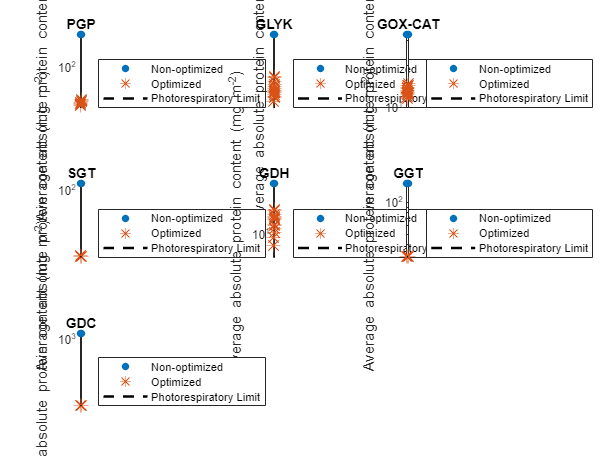

figure;
% Plot semilogy graphs of Ci (x) against absolute protein concentrations of individual enzymes 
for j = 1:length(PR_indices) % For each enzyme j 
    PR_index = PR_indices(j);
    nexttile
    switch (plottype)
        case 'opt'
        semilogy(Ci, enzyme_nopt_concs(PR_index,:), '.', 'MarkerSize', 15);
        hold on
        semilogy(Ci, all_opt_concs(PR_index,:), '*', 'MarkerSize', 10);
        hold on
        % Plot PR constraints levels
        semilogy(Ci, PR_limits(j,:), '--', 'Color','black','LineWidth', 1.75); 
        xlim([min(Ci), max(Ci)]); % Ci x axis limits
        ylim([0,inf]) % Protein y axis limits 
        xticks(Ci)
        xticklabels(Ci)
        yticks([0 10^1 10^2 10^3 10^4])
        yticklabels({'0','10^1','10^2','10^3','10^4'})
        xlabel('C_i (ppm)','FontSize', 10);
        ylabel('Average absolute protein content (mg m^{-2})','FontSize', 10);
        title(enzymes(PR_index))
        %grid on
        hold off
        legend('Non-optimized','Optimized','Photorespiratory Limit','Location', 'SouthEastOutside')
        %%%OR only one series for fold change
        case 'FC'
        semilogy(Ci, all_opt_FC(PR_index,:),'blue','filled','^'); % Plot fold change series
        hold on
        xlim([min(Ci), max(Ci)]); % Ci x axis limits
        ylim([0,inf]) % Protein y axis limits 
        xticks(Ci)
        xticklabels(Ci)
        xlabel('C_i (ppm)','FontSize', 10);
        ylabel('Fold change protein content','FontSize', 10);
        title(enzymes(PR_index))
        %grid on
        hold off
     end
end
set(gcf, 'PaperOrientation', 'landscape');
print(gcf,fullfile('Outputs/rice_params/graphs',"Ci_vs_PR_Enzymes_log"),'-dpdf','-fillpage');

Create SS panel

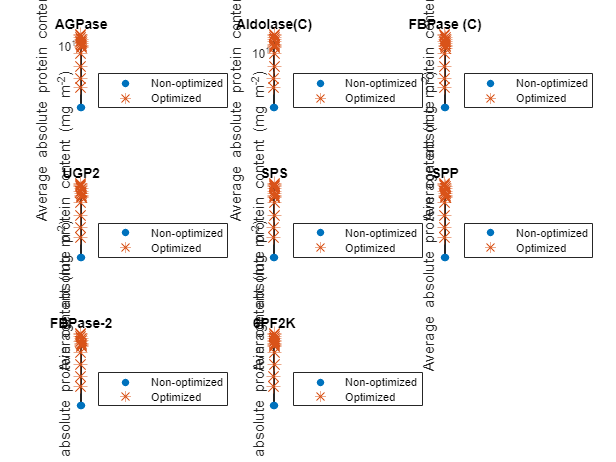

figure;
% Plot semilogy graphs of Ci (x) against absolute protein concentrations of individual enzymes 
for j = 1:length(SS_indices) % For each enzyme j 
    SS_index = SS_indices(j);
    nexttile
        switch (plottype)
        case 'opt'
        semilogy(Ci, enzyme_nopt_concs(SS_index,:), '.', 'MarkerSize', 15);
        hold on
        semilogy(Ci, all_opt_concs(SS_index,:), '*', 'MarkerSize', 10);
        xlim([min(Ci), max(Ci)]); % Ci x axis limits
        ylim([0,inf]) % Protein y axis limits 
        xticks(Ci)
        xticklabels(Ci)
        yticks([0 10^1 10^2 10^3 10^4])
        yticklabels({'0','10^1','10^2','10^3','10^4'})
        xlabel('C_i (ppm)','FontSize', 10);
        ylabel('Average absolute protein content (mg m^{-2})','FontSize', 10);
        title(enzymes(SS_index))
        %grid on
        hold off
        legend('Non-optimized','Optimized','Location', 'SouthEastOutside')
        %%%OR only one series for fold change
        case 'FC'
        semilogy(Ci, all_opt_FC(SS_index,:),'blue','filled','^'); % Plot fold change series
        hold on
        xlim([min(Ci), max(Ci)]); % Ci x axis limits
        ylim([0,inf]) % Protein y axis limits 
        xticks(Ci)
        xticklabels(Ci)
        xlabel('C_i (ppm)','FontSize', 10);
        ylabel('Fold change protein content','FontSize', 10);
        title(enzymes(SS_index))
        %grid on
        hold off
        end
end
set(gcf, 'PaperOrientation', 'landscape');
print(gcf,fullfile('Outputs/rice_params/graphs',"Ci_vs_SS_Enzymes_log"),'-dpdf','-fillpage');